distance=100;
%Input Function
[Power_mW,dBm]=fri(100e-03,1,11.35,15e-03,1,distance)

Power_mW = 	1.0e+-3 *

       Inf    0.1078    0.0270    0.0120    0.0067    0.0043    0.0030    0.0022    0.0017    0.0013    0.0011    0.0009    0.0007    0.0006    0.0006    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000


dBm =        Inf   -9.6733  -15.6939  -19.2158  -21.7145  -23.6527  -25.2364  -26.5753  -27.7351  -28.7582  -29.6733  -30.5012  -31.2570  -31.9522  -32.5959  -33.1952  -33.7557  -34.2823  -34.7788  -35.2484  -35.6939  -36.1177  -36.5218  -36.9079  -37.2776  -37.6321  -37.9728  -38.3006  -38.6165  -38.9213  -39.2158  -39.5006  -39.7763  -40.0436  -40.3029  -40.5547  -40.7994  -41.0374  -41.2690  -41.4946  -41.7145  -41.9290  -42.1383  -42.3427  -42.5424  -42.7376  -42.9285  -43.1153  -43.2982  -43.4772


[Power_mW_O,dBm_O]=fri(100e-03,1,6,15e-03,1,distance)

Power_mW_O = 	1.0e+-4 *

       Inf    0.5699    0.1425    0.0633    0.0356    0.0228    0.0158    0.0116    0.0089    0.0070    0.0057    0.0047    0.0040    0.0034    0.0029    0.0025    0.0022    0.0020    0.0018    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0008    0.0008    0.0007    0.0007    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002


dBm_O =        Inf  -12.4418  -18.4624  -21.9842  -24.4830  -26.4212  -28.0048  -29.3437  -30.5036  -31.5266  -32.4418  -33.2696  -34.0254  -34.7206  -35.3643  -35.9636  -36.5242  -37.0508  -37.5472  -38.0168  -38.4624  -38.8862  -39.2902  -39.6763  -40.0460  -40.4006  -40.7412  -41.0690  -41.3849  -41.6897  -41.9842  -42.2690  -42.5448  -42.8121  -43.0714  -43.3231  -43.5678  -43.8058  -44.0374  -44.2631  -44.4830  -44.6974  -44.9068  -45.1111  -45.3108  -45.5060  -45.6969  -45.8837  -46.0666  -46.2457


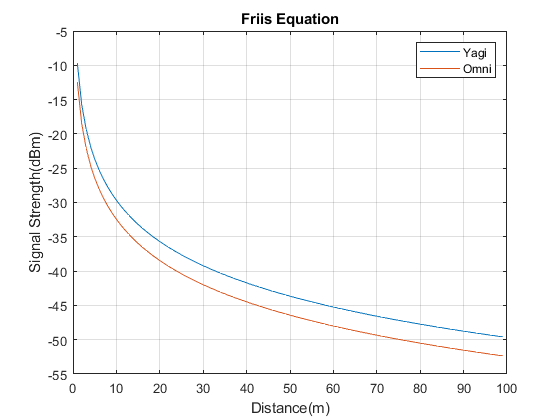


%pt-Power transmitted
%Gt-Transmitted Gain
%Gr-Recived Gain
%lambda_squared-Lambda Squared
%L-Systems losses
range=0:1:distance-1;
plot(range,dBm,range,dBm_O)
title('Friis Equation')
xlabel('Distance(m)')
ylabel('Signal Strength(dBm)')
legend('Yagi','Omni')
grid on

Friss Formula

function [pr,dbm]=fri(pt,Gr,Gt,lambda_squared,L,distance)
d=0:1:distance-1;
pr=(pt*Gr*Gt*lambda_squared)./((4^2)*(pi^2)*d.^2*L);
dbm=10*log10(pr)+30;
end
